Show how we can add together several shorter exposures -- even with camera motion -- to simulate a single longer exposure

First, set up a default scenario

ieInit;
useScene = 'pavilion-day';
useScene = 'pavilion-night';
useScene = 'MacBethChecker';
useScenario = ivScenario(useScene);

% ivScenario has defaults, but we can over-ride them
useScenario.exposureTime = .015; % 1/30;
useScenario.clipLength = .060; %1/15;
useScenario.raysPerPixel = 1024;
useScenario.fastPreview = 1;

% Save short exposure for later use
shortExposure = useScenario.exposureTime;

% calculate how many frames we need to add together
numFrames = round(useScenario.clipLength / useScenario.exposureTime);

Now we can modify settings or accept the default, and then create our video clips

sceneVideoClip(useScenario); % multi-capture

[INFO]: Read 25 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 2 assets; parsed up to line 109
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye
Elapsed time is 0.172150 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,743 bytes  received 593 bytes  1,557.33 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-djc4481 sh -c " pbrt  --gpu  --outfile /home/david81/ISETRemoteRender/MacBethChecker/renderings/MacBethChecker.exr /home/david81/ISETRemoteRender/MacBethChecker/MacBethChecker.pbrt "
[INFO]: Rendered remotely in: 66.78 sec
[INFO]: Downloading data:
[INFO]: Sent 46 bytes  received 3,898,070 bytes  2,598,744.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/MacBethChecker.exr
Elapsed time is 0.155621 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,742 bytes  received 589 bytes  1,554.00 bytes/sec
[INFO]: Data u

% Single (longer) capture
useScenario.exposureTime = useScenario.clipLength;
sceneVideoClip(useScenario);

[INFO]: Read 25 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 2 assets; parsed up to line 109
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye
Elapsed time is 0.156160 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,748 bytes  received 593 bytes  4,682.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-gpu-djc4481 sh -c " pbrt  --gpu  --outfile /home/david81/ISETRemoteRender/MacBethChecker/renderings/MacBethChecker.exr /home/david81/ISETRemoteRender/MacBethChecker/MacBethChecker.pbrt "
[INFO]: Rendered remotely in: 67.08 sec
[INFO]: Downloading data:
[INFO]: Sent 46 bytes  received 5,373,674 bytes  3,582,480.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/MacBethChecker.exr
Local cpCam ran  in: 37.5 seconds of CPU time.
Total cpCam ran  in: 79.3944 total seconds.


By default, results are in local/synthetic-scene-tests, labeled with their exposure time in ms,  and the frame number in the multi-frame sequence.

We call sceneSynthesize both on the multiple exposures to sum them up,  and on the longer exposure(s) which we want to compare. 

We do this even for the case of a single longer exposure because it also does some baseline processing of the raw scene.

Typically the "start" frame is 001, so we've currently hard-coded that.

sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(shortExposure * 1000))),numFrames);
sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(useScenario.clipLength * 1000))),1);

NOTE: We need to move the generated files to generated, or put them there right away:)

Now we can compare the synthesized scene(s).

sceneHomeDir =  ivDirGet('computed');
% scene names have 3 codes:
% * exposureTime in ms
% * first frame in series (typically 001)
% * last frame in series (typically 001 or numFrames)
[sensorSingle, sensorMulti] = sceneCompare( ...
    fullfile(sceneHomeDir,sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(shortExposure*1000), 1, numFrames)), ...
    fullfile(sceneHomeDir, sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(useScenario.exposureTime*1000),1,1)), useScenario.exposureTime);

Denoised in: 20.143
Denoised in: 20.248


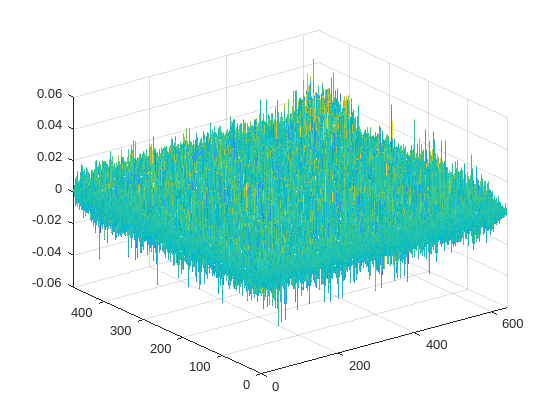

% Show results
mesh(sensorSingle.data.volts - sensorMulti.data.volts);

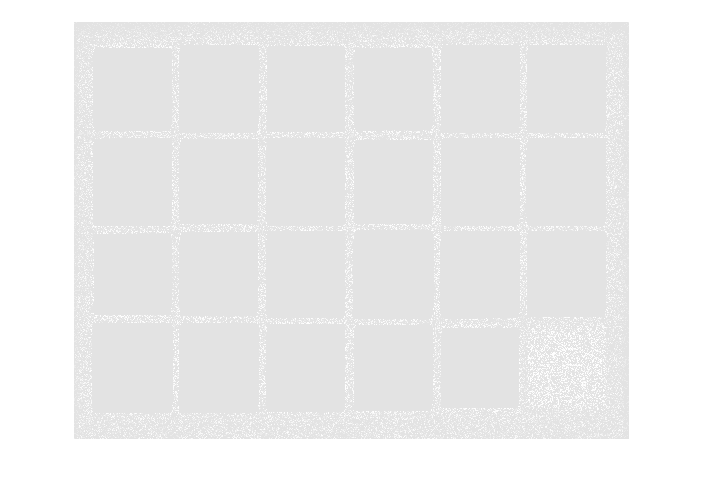


imshow(histeq(sensorSingle.data.volts - sensorMulti.data.volts));